Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Beam optics tutorial (Section 3.3.1)

Volker Ziemann, 211106, CC-BY-SA-4.0

In this tutorial we'll develop a first beam optics code that allows us to track single particles, or "rays" through a sequence of drift spaces and thin lenses. Let's therefore first clear the MATLAB workspace and define anonymous functions (those with an '@') that return the transfer matrices. Here D(L) will return the 2x2 matrix for a drift space and Q(F) that of a thin lens with focal length F

clear all; close all
D=@(L)[1,L;0,1];
Q=@(F)[1,0;-1/F,1];

Now it is easy to obtain the transfer matrix of a beam line consisting of a sequnece of such elements. For  example, a beamline, where the first element is a drift space with a length of 2m, followed by a lens with a focal length of 1 m and a second drift space having a length of 3m.

A=D(3)*Q(1)*D(2)

A =     -2    -1
    -1    -1


I suggest to verify the numerical calculation by multiplying the individual matrices by hand on a peice of paper.

Directly coding the matrix multiplications is inconvenient and we therefore introduce a very simple way to describe sequences of elements as an array, here called `fodo.` This array has four columns with the following interpretations

- First column: code, drift=1, quad=2

- Second column: repeat code for the element

- Third column: length of one segment

- Fourth column: strength of one segment, focal length for a thin quadrupole.

The second column with the repeat code is not strictly necessary but will make the graphs easier to interpret, because we can plot many intermediate points, rather than connecting values at the end of elements by a straight line.

This particular sequence starts with an element having a 1 in the first column and is therefore a drift space. It consists of 5 segments, each 0.2 m long. The last column is not used here and contains a zero, The next element is a lens, beacuse the first code is 2 and it is defocusing, because the fourth column contains a negative number for the focal length. The third element is again a driftspace, this time with 10 segments of 0.2 m, followed by  a focusing lens and another drift space. Such a sequence of focusing lens, drift space, defocusing lens and another drift space is usually referred to as a FODO (get it?) cell.  

F=2.1;
fodo=[1,   5,  0.2,   0;
      2,   1,    0,  -F;
      1,  10,  0.2,   0;
      2,   1,    0,   F;
      1,   5,  0.2,   0]   

fodo =     1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -2.1000
    1.0000   10.0000    0.2000         0
    2.0000    1.0000         0    2.1000
    1.0000    5.0000    0.2000         0


Now we build our beamline as a sequence of one or many FODO cells. The latter we achieve by simply concatenating` fodo` vertically (note the semicolon!). We will always use` beamline` as a reserved name of the beamline that we work on.

%beamline=fodo;             % one cell
%beamline=[fodo;fodo]       % two cells
beamline=repmat(fodo,10,1)  % ten cells

beamline =     1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -2.1000
    1.0000   10.0000    0.2000         0
    2.0000    1.0000         0    2.1000
    1.0000    5.0000    0.2000         0
    1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -2.1000
    1.0000   10.0000    0.2000         0
    2.0000    1.0000         0    2.1000
    1.0000    5.0000    0.2000         0


Before we can assemble the transfer matrices, we have to do a bit of accounting, like counting the number of elements `nlines` in the beamline description and the number `nmat` of matrices that we will need to store the matrices. This is just given by the sum of the segments in the second column plus one. Next we allocate space for the nmat $2\times 2$ matrices in the array Racc and initialize the first matrix as the $2\times2$unit matrix eye(2). This additional matrix at the beginning accounts for the "plus one" in the definition of` nmat`. Finally we allocate the array `spos` to store the position of each segment along the beam line.

nlines=size(beamline,1)

nlines = 50

nmat=sum(beamline(:,2))+1;
Racc=zeros(2,2,nmat);
Racc(:,:,1)=eye(2);
spos=zeros(nmat,1);

Now we are ready to loop through the beamline description by looping over the lines, labeled by` line`, and then over the segments, labeled by `seg`. As we do that we increment the counter` ic` that keeps track of which segment we're currently working on. Then we initialize the transfer matrix of the current segment `Rcurr` by the unit marix before looking at the first column to decide whether the element is a drift space or a lens and fill `Rcurr` with the appropriate transfer matrix. In` case` the first column (`beamline(line,1)`) is a 1, it is a drift and we use the value from the third column as the length of the drift space. In `case` the first column contains a 2, it is a lens and we use the focal length from the fourth column as the argument to the function `Q(F).` In case we encounter any other number in the first column, we display a warning. At this point `Rcurr` contains the transfer matrix for the current segment and we find **the transfer matrix from the start of the beamline to the end of the current element** `Racc(:,:,ic)` by left-multiplying Rcurr to `Racc(:,:,ic-1)` which already contains the transfer matrix from the start to the end of he previous segment. Finally we calculate the position `spos(ic)` of the current segment from that of the previous segment `spos(ic-1)` by adding the length of the current segment to it.

ic=1;
for line=1:nlines
  for seg=1:beamline(line,2)
    ic=ic+1;
    Rcurr=eye(2);
    switch beamline(line,1)
      case 1
        Rcurr=D(beamline(line,3));
      case 2
        Rcurr=Q(beamline(line,4));
      otherwise
        disp('unknown element');
    end
    Racc(:,:,ic)=Rcurr*Racc(:,:,ic-1);
    spos(ic)=spos(ic-1)+beamline(line,3);    
  end
end

At this point` Racc` contains all trasnfer matrices from the start of the beam line to the end of each and every segment while `spos` contains the positions of each segment.

Now we can use the transfer matrices to plot the trajectory of a particle with starting coordinates $x_0 = 0$ and $x_0'=10^{-3}$ rad by mapping the initial (column) vector `x0 `with `Racc` to the ened of each segment and record both position` x(1)` and angle `x(2)` in the previously allocated array `data`. 

data=zeros(nmat,2); 
x0=[0;1e-3];
for k=1:nmat
  x=Racc(:,:,k)*x0;
  data(k,1)=x(1);
  data(k,2)=x(2);
end

Now we can plot the trajectory and annotate the axes.      

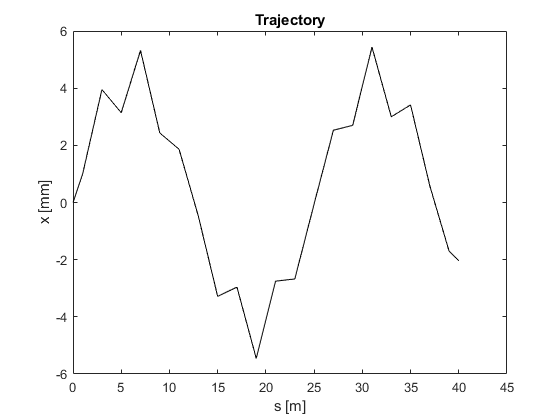

plot(spos,1000*data(:,1),'k')     
xlabel('s [m]')
ylabel('x [mm]') 
title('Trajectory')

We observe an oscillation of the particle's position along the beam line. This type of transverse oscillation is usually called *betatron oscillation*.

Now you can go back to the start of the script and change the focal length F and observe how the oscillation changes. You might also want to increase the length of the beam line by adding more copies of the FODO cells in the definition of beamline by increasing the number of copies in `repmat()`. Explore!

Calculating transfer matrices is a task we repeatedly have to do and it is therefore convenient to encapsulate the code that does that in a dedicated function; we call it `calcmat().` It receives the `beamline` as input and returns `Racc, spos,nmat`, and` nlines`. Internally it calculates nmat and nlines and then allocates arrays for `Racc `and `spos` and then loops over all lines and segments, just as we did in the code above. We use such a function in the following way

[Racc,spos,nmat,nlines]=calcmat(beamline);

and--viola--all transfer matrces and the positions of all segments are immediately available. Here is the definition of the function `calcmat()`

function [Racc,spos,nmat,nlines]=calcmat(beamline)
nlines=size(beamline,1);
nmat=sum(beamline(:,2))+1;
Racc=zeros(2,2,nmat);
Racc(:,:,1)=eye(2);
spos=zeros(nmat,1);
ic=1;
for line=1:nlines
  for seg=1:beamline(line,2)
    ic=ic+1;
    Rcurr=eye(2);
    switch beamline(line,1)
      case 1
        Rcurr=D2(beamline(line,3));
      case 2
        Rcurr=Q2(beamline(line,4));
      otherwise
        disp('unknown element');
    end
    Racc(:,:,ic)=Rcurr*Racc(:,:,ic-1);
    spos(ic)=spos(ic-1)+beamline(line,3);    
  end
end
end

Inside this function the function D(L) an Q(F) are unknown. We could either copy the two lines with their definitions into calcmat, or define additional functions that provide the same functionality. First for the drift space

function out=D2(L)
out=[1,L;0,1];
end

and for the lens

function out=Q2(F)
out=[1,0;-1/F,1];
end

Here I have given new names (D2, Q2)to functions for drift and quad, because the names  "D" and "Q" are already used for the matrices in the first few lines of this script.

These service functions will make all further examples much more compact and readable, because we never have to copy and paste the enclosed code verbatim into our scripts. This simple tutorial only contains the bare essentials of beam optics calculations. Have a look at the web site where you picked this script up and check out the other more advanced examples. 